Abdullah Ahmed

aa09303

Lab -2

**Task 1**

a = complex(15.5, 3.175);
[xb, yb] = pol2cart(deg2rad(45), 5);
b = complex(xb, yb);

% a)
real(a)
real(b)

% b)
imag(a)
imag(b)

% c)
conj(a)
conj(b)

% d)
angle(a)
angle(b)

% e)
abs(a)
abs(b)

**Try 1**

n = 0:10;
y = cos(n);

figure;
plot(n, y, ':o');

figure;
stem(n, y);

**Try 2**

Ts = 0.1; 
t = 0:Ts:10;
y = cos(t);

figure;
subplot 121;
plot(t, y, ':o');

subplot 122;
stem(t, y);

**Task 2 (a)**

n = 0:10;
y = cos(n);

figure;
plot(n, y, ':o');
title("continous");
xlabel("time");
ylabel("amplitude");

figure;
stem(n, y);
title("discrete");
xlabel("samples");
ylabel("amplitude");

Ts = 0.1; 
Fs = 1/Ts;
t = 0:Ts:10;
n=1:length(t);
y = cos(t);

figure;
subplot 121;
plot(t, y, ':o');
title("continous");
xlabel("time");
ylabel("amplitude");

subplot 122;
stem(n, y);
title("discrete");
xlabel("samples");
ylabel("amplitude");

**Task 2 (b)**

fs = 50;
ts = 1/fs;
t = 0:ts:3;
func = 3 * exp(-t) .* cos(20 * t + pi / 3);
figure;
stem(1:length(t), func);
title("discrete");
xlabel("samples");
ylabel("amplitude");

**Try 3**

clc; clear
t = -20:1:20;
y = mod(t,5);
z = t>=0;

subplot(1,2,1);
stairs(t,z,'linewidth',2);

subplot;
title('Unit-step signal');
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 0 1.1]);

subplot(1,2,2);
plot(t,y,'linewidth',1.5);
title('Sawtooth signal');
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 0 5.2]);

**Task 3**

t = -20:0.1:20;
y = sawtooth(t, 0);
z = t>=0;

figure;
plot(t, y, "blue");
hold on;
plot(t, z, "red");
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 0 1.2]);
legend("sawtooth", "unit step");

**Task 4**

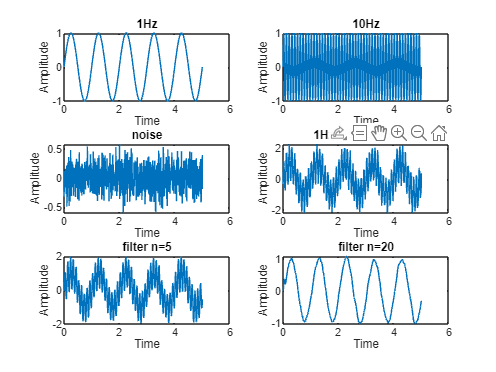

t = 0:0.005:5;
f1 = 1;
f2 = 10;
xt1 = sin(2*pi*f1*t);
xt2 = sin(2*pi*f2*t);
noise = 0.2 * randn(size(t));

yt = xt1 + xt2 + noise;
zt1 = filter(ones(1,5)/5 , 1, yt);
zt2 = filter(ones(1,20)/20 , 1, yt);

subplot 321;
plot(t, xt1);
title("1Hz")
xlabel('Time');
ylabel('Amplitude');

subplot 322;
plot(t, xt2);
title("10Hz")
xlabel('Time');
ylabel('Amplitude');

subplot 323;
plot(t, noise);
title("noise")
xlabel('Time');
ylabel('Amplitude');

subplot 324;
plot(t, yt);
title("1Hz + 10Hz + noise")
xlabel('Time');
ylabel('Amplitude');

subplot 325;
plot(t, zt1);
title("filter n=5")
xlabel('Time');
ylabel('Amplitude');

subplot 326;
plot(t, zt2);
title("filter n=20")
xlabel('Time');
ylabel('Amplitude');